# **Lab #4: Aliasing due to Undersampling**

This lab is based upon the problems in Section 7.1, "Aliasing due to Undersampling," in the course text *Computer Explorations in SIGNALS AND SYSTEMS* by Buck, Daniel, Singer.   

In this lab, you will explore the effect of aliasing due to undersampling on signals reconstructed by bandlimited interpolation. The lab makes use of the relationship between the CTFT of a periodic signal $x(t)$ and the DTFT of its samples $x[n]$, as well as the relationship between the DTFT of the samples $x[n]$ and the DTFS of $x[n]$.

In the following problems, you will examine the effects of undersampling a pure sinusoid and a chirp signal. 

**Problem 1: Sampling pure sinusoidal signals**

Consider the sinusoidal signal 

                         
$$\quad \quad \quad \quad x(t)=sin(\Omega_0 t).$$


If $x(t)$ is sampled with frequency $\Omega_s=2\pi/T$ rad/sec, then the discrete-timne signal $x[n]=x(nT)$ is equal to 

                       
$$\quad \quad \quad \quad x[n]=sin(\Omega_0 nT).$$


Assume the sampling frequency is fixed at $\Omega_s = 2\pi(8192)$ rad/sec.

**Task 1.** Assume  $\Omega_0 = 2\pi(1000)$rad/sec and define `T=1/8192`. Create the vector` n=[0:8191]`, so that` t=n*T` contains the 8192 time samples of the interval $0 \leq t \leq 1$. Create a vector `x` which contains the samples of  $x(t)$at the time samples in `t`.

 % Define the sampling frequency
T = 1/8192;
fs = 2*pi/T; % rad/sec
n = 0:8191;
t = n*T;


w0 = 2*pi*1000;
x = sin(w0*t);







**Task 2. **Display the first fifty samples of $x[n]$ versus $n$ using `stem`. Display the first fifty samples of $x(t)$ versus the sampling times  using `plot`. (Use` subplot` to simultaneously display the two plots.)

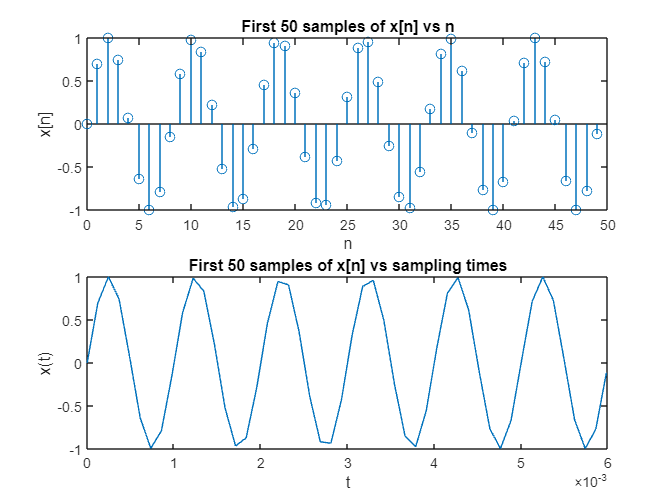


figure;
subplot(2,1,1);
stem(n(1:50), x(1:50));
title('First 50 samples of x[n] vs n');
xlabel('n');
ylabel('x[n]');

subplot(2,1,2);
plot(t(1:50), x(1:50));
title('First 50 samples of x[n] vs sampling times');
xlabel('t');
ylabel('x(t)');

Note that `plot(t,x)` displays a continuous-time  signal given the samples in `x`, using straight lines to interpolate between sample values. While this interpolation is not generally equal to the bandlimited reconstruction which follows from the sampling theorem, it can often be a very good approximation if the sampling rate is high enough. 

To compute samples of the  CTFT of  the bandlimmited reconstruction $x_r(t)$, we use the following function:

%function [X,f] = ctfts(x,T)
% CTFTS calculates the CTFT of a periodic signal x(t) which is reconstructed
% from the samples in the vector x using ideal bandlimited interpolation.
% the vector x contains samples x(t) over an integer number of periods, and
% T contains the sampling period. 
% 
% The vector X contains the area of the impulses at frequency values stored
% in the vector f.
%
% This function makes use of the relationship between the CTFT  of x(t) and
% the DTFT of its samples x[n], as well as the relationship between the
% DTFT of the samples x[n] and the DTFS of x[n].
% N=length(x);
% X=fftshift(fft(x,N))*(2*pi/N);
% f=linspace(-1,1-1/N,N)/(2*T);
%end

`This  function  uses fft to calculate the Fourier transform  of the reconstructed signal. `

**Task 3. **Use `[X,f]=ctfts(x,T)` to calculate the CTFT of the reconstructed signal $x_r(t)$. Plot the magnitude of `X` versus `f`.  Is `X` nonzero at the proper frequency values? (Note that almost all of the elements in `X` are nonzero, but most are small values due to numerical round-off errors) Is the phase of `X` correct, assuming that the phase is equal to zero when `X` is nearly zero, i.e., nonzero only due to round-off  error?

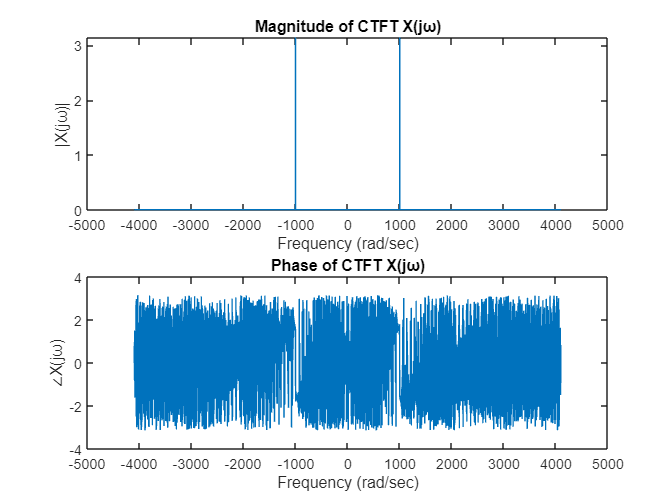

% Task 3: Calculate CTFT of reconstructed signal
[X, f] = ctfts(x, T);

figure;
subplot(2,1,1);
plot(f, abs(X));
title('Magnitude of CTFT X(jω)');
xlabel('Frequency (rad/sec)');
ylabel('|X(jω)|');

subplot(2,1,2);
plot(f, angle(X));
title('Phase of CTFT X(jω)');
xlabel('Frequency (rad/sec)');
ylabel('∠X(jω)');

The phase of X is correct, assuming that the phase is equal to zero when X is nearly zero

**You will now consider  the  effect  of aliasing on the  reconstructed  signal when sampling  pure sinusoidal signals of different frequencies.**

**Task 4.  **Repeat Tasks 1 - 3 for the sinusoidal frequencies $\Omega_0 = 2\pi (1500)$ and $2\pi(2000)$ rad/sec. Again, is the magnitude of $X$ nonzero for the expected frequencies? Is the phase of $X$ correct?

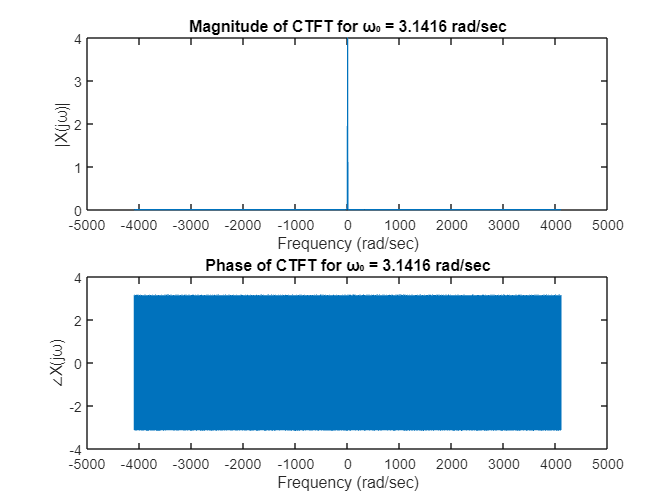

% Task 4: Repeat for other frequencies
frequencies = [2*pi*1500, 2*pi*2000, pi];

for i = 1:length(frequencies)
    w0 = frequencies(i);
    x = sin(w0*t);
    
    % Calculate CTFT
    [X, f] = ctfts(x, T);
    
    figure;
    subplot(2,1,1);
    plot(f, abs(X));
    title(['Magnitude of CTFT for ω₀ = ' num2str(w0) ' rad/sec']);
    xlabel('Frequency (rad/sec)');
    ylabel('|X(jω)|');
    
    subplot(2,1,2);
    plot(f, angle(X));
    title(['Phase of CTFT for ω₀ = ' num2str(w0) ' rad/sec']);
    xlabel('Frequency (rad/sec)');
    ylabel('∠X(jω)');
    
    % Play the sound
    sound(x, 1/T);
    pause(2); % Pause to hear each sound
end

Yes X is as expected from the previously found conclusions for it. 

the max and phase is correct but harder to see because of the aliasing

**Task 5. **Play each of the sampled signals created in Task 4 using sound(x,1/T).  Does the pitch of the tone  that you hear increase with increasing frequency $\Omega_0$? Note that, like plot, the function sound performs   interpolation. In essence, your computer  converts the DT signal in MATLAB  into a CT  signal using a digital-to-analog converter, and then plays this CT signal on its speaker.  

the sound here was played above in the loop for simiplicity. The pitchin increasing with the increasing frequency, it is very easy to hear when sped up then slowed down again

**Task 6.** Now repeat Tasks 1 and 3 - but not Task 2 - for the sinusoidal frequencies $\Omega_0 = 2\pi (3500), \Omega_0 = 2\pi (4000), \Omega_0 = 2\pi (4500), \Omega_0 = 2\pi (5000), $ and  $\Omega_0=2\pi(5500)$ rad/sec.  Also play each sample signal using `sound`. Does  the pitch of  the tone  that you hear  increase with each increase in the frequency $\Omega_0$? If  not, can you explain the behavior?

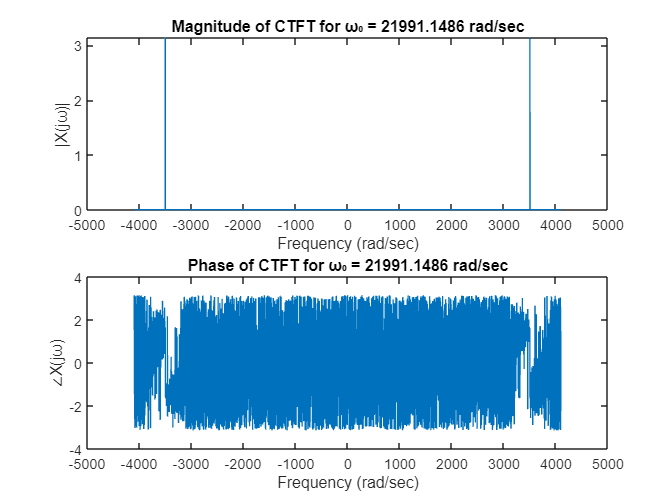

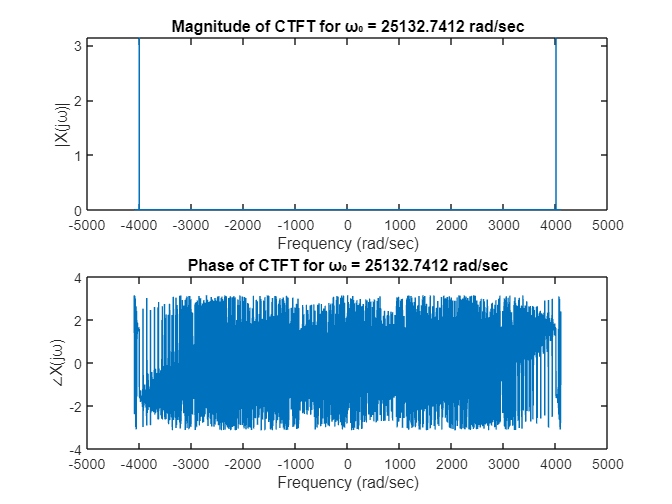

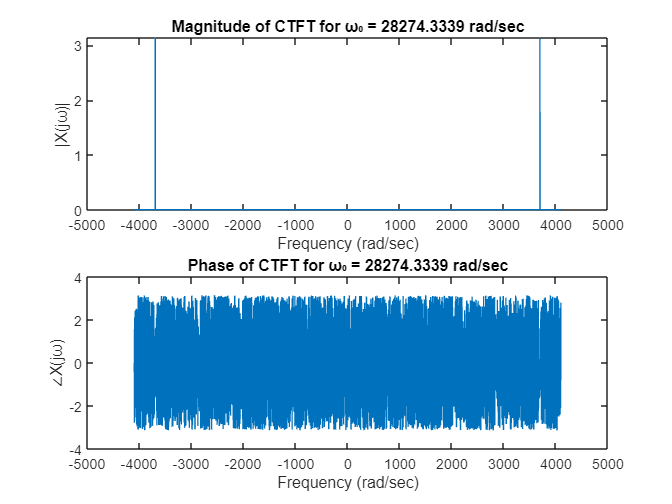

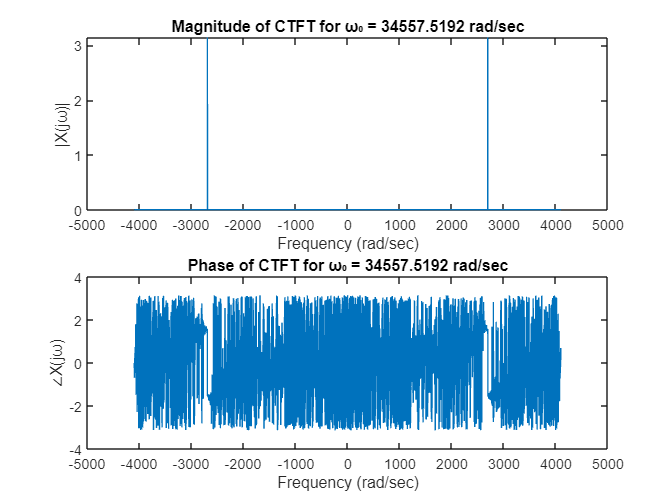

frequencies = [2*pi*3500, 2*pi*4000, 2*pi*4500,2*pi*5000, 2*pi*5500];

for i = 1:length(frequencies)
    w0 = frequencies(i);
    x = sin(w0*t);
    
    % Calculate CTFT
    [X, f] = ctfts(x, T);
    
    figure;
    subplot(2,1,1);
    plot(f, abs(X));
    title(['Magnitude of CTFT for ω₀ = ' num2str(w0) ' rad/sec']);
    xlabel('Frequency (rad/sec)');
    ylabel('|X(jω)|');
    
    subplot(2,1,2);
    plot(f, angle(X));
    title(['Phase of CTFT for ω₀ = ' num2str(w0) ' rad/sec']);
    xlabel('Frequency (rad/sec)');
    ylabel('∠X(jω)');
    
    % Play the sound
    sound(x, 1/T);
    pause(2); % Pause to hear each sound
end

The frequency does not always increase, in fact, when it equals the nyquist rate, resulting in the same sample value repeated (aliasing). This occurs when we hear the signal dampen or get quiter, as well as sounding monotone or similar to a factor frequency that has similar properties because of the sampling. 

**Problem 2: Sampling a chirp signal**

Now  consider  the signal

                          $\quad \quad \quad \quad x(t)=sin(\Omega_0 t + \frac{1}{2}\beta t^2)$, 

which is often called a chirp signal due to  the sound it makes when played through a loudpeaker. The "chirp" sound is due to the  increasing instantaneous frequency of  the signal   over time.  The instantaneous frequency of a  sinusoidal   signal is given by the derivative  of  its phase, i.e.,  the argument of $sin(\cdot)$. For the chirp signal,  the instantaneous frequency is 

                         
$$\quad \quad \quad \quad \Omega_{\rm inst}  = \frac{d}{dt} \left(\Omega_0 t + \frac{1}{2} \beta t^2 \right) \\
\quad \quad  \quad \quad \quad \quad = \Omega_0 + \beta t .


 $$


Assume  for  the following  problems  that the sampling frequency is $\Omega_s= 2\pi(8192)$ rad/sec. 

**Task 1. Set **$\Omega_0= 2\pi(3000)$ rad/sec and $\beta = 2000$ rad/sec${}^2$. Store in the vector `x1`  the samples  of the chirp signal on the interval $0 \leq t \leq 1.$


fs = 2*pi* 8192; 
T = 1/8192;
n = 0:8191;
t = n*T;
a = 2*pi*(8192);
b = 2000;
x1 = sin(a*t + b*t.^2);

**Task 2.**  Use `sound` to play the chirp signal contained in `x1.` Can you explain what  you just heard?


sound(x1, 1/T);
pause(5)

The sound that was played sounded like a whooop

**Task 3. **Store in the vector `x10`  the samples  of the chirp signal on the interval $0 \leq t \leq 10$, and play the signal  `x10` using `sound`. Determine (using  a  stopwatch) the approximate time sample at which the played signal  has its maximum pitch (apparent frequency). Given the linear equation for instantaneous frequency and your understanding of aliasing, explain how you could  have  predicted this time sample.

f(t) = (1/2pi) * d/dt(phase)


n10 = 0:81919;
t10 = n10*T;
x10 = sin(a*t10 + b*t10.^2);
sound(x10, 1/T);
pause(10)

The maximum pitch here is about 5 seconds because thats when the sampling frequency is about twice the nyquist frequency would would be the last point before aliasing and then the lower frequencies after, so in summary goes up to that point then back down (pitch).  also when the phase changes very quickly

**Task 4. **Store in the vector `x20`  the samples  of the chirp signal on the interval $0 \leq t \leq 20$, and play the signal  `x20` using `sound`.Determine (using  a  stopwatch) the approximate time sample at which the played chirp signal  has zero (or very low) frequency. Explain how you could  have  predicted this time sample.


n20 = 0:163839;
t20 = n20*T;
x20 = cos(a*t20 + b*t20.^2);
sound(x20, 1/T);


The chirp signal has very low frequency to the end of the signal, hard to measure a specific time becuase all sounds play one after the other even when just running the one section but I doubled the time and samples so by the given increase it could be predicted to be the end of the signal or the last part of the sound played (and before the 10 seconds. Aliasing from going over twice the nyquist rate (multiples of 5 seconds would be the high (and low) pitches)

function [X,f] = ctfts(x,T)
% CTFTS calculates the CTFT of a periodic signal x(t) which is reconstructed
% from the samples in the vector x using ideal bandlimited interpolation.
% the vector x contains samples x(t) over an integer number of periods, and
% T contains the sampling period. 
% 
% The vector X contains the area of the impulses at frequency values stored
% in the vector f.
%
% This function makes use of the relationship between the CTFT  of x(t) and
% the DTFT of its samples x[n], as well as the relationship between the
% DTFT of the samples x[n] and the DTFS of x[n].
N=length(x);
X=fftshift(fft(x,N))*(2*pi/N);
f=linspace(-1,1-1/N,N)/(2*T);
end